# Tracking a Car-Like Robot Using Particle Filter as it Traverses Through a Cave 

## Initialize a Car-like Robot

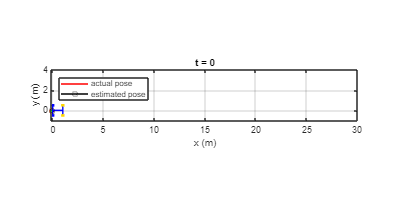

rng('default'); % for repeatable result
dt = 0.05; % time step
initialPose = [0  0  0  0]';
carbot = ExampleHelperCarBot(initialPose, dt);

## Main Loop

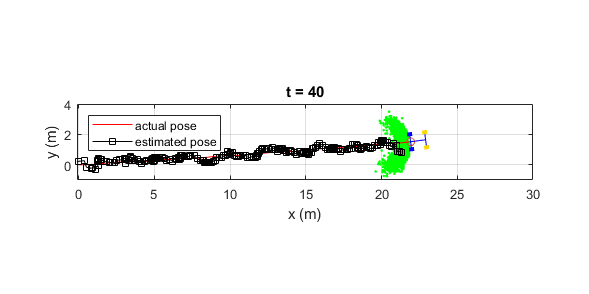

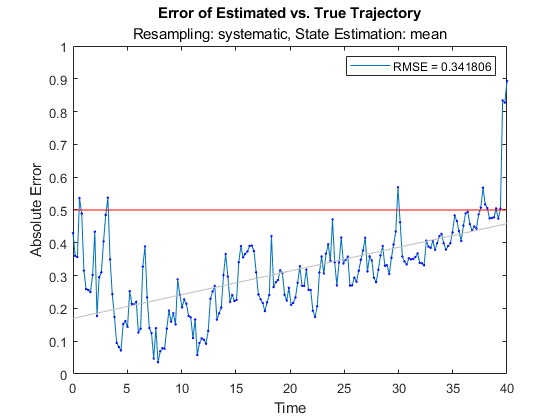

RMSE = 0.341806

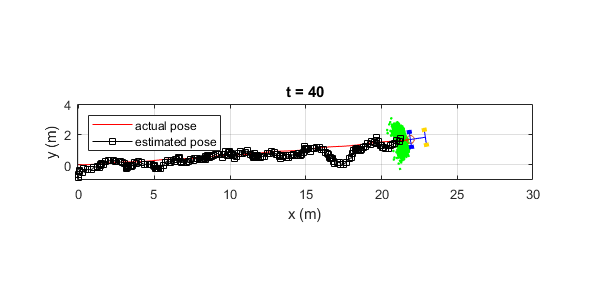

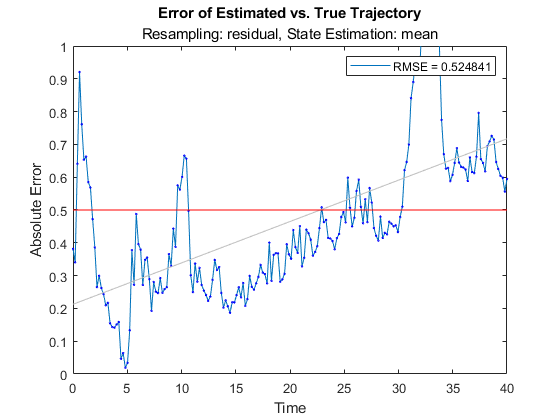

RMSE = 0.524841

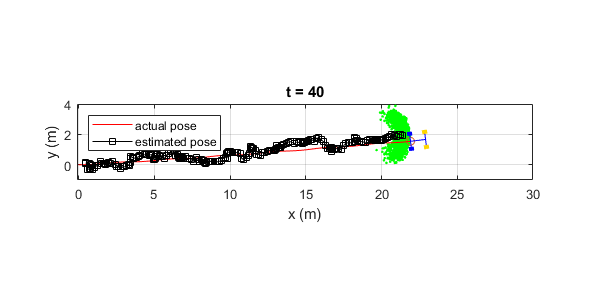

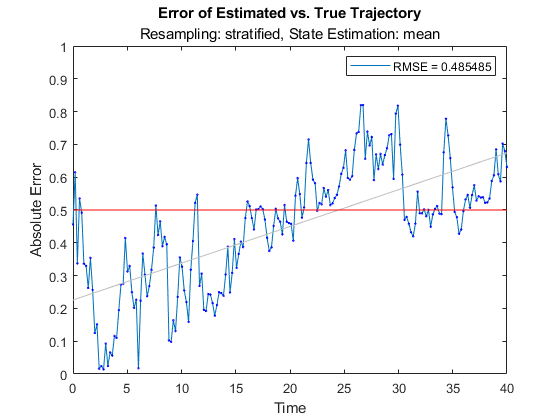

RMSE = 0.485485

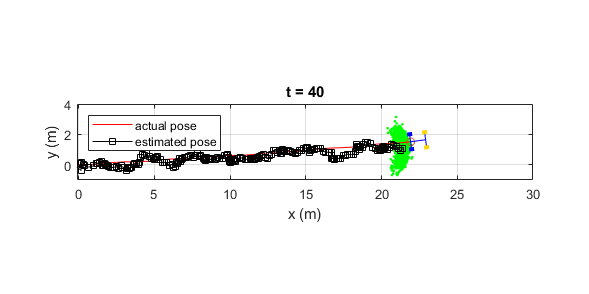

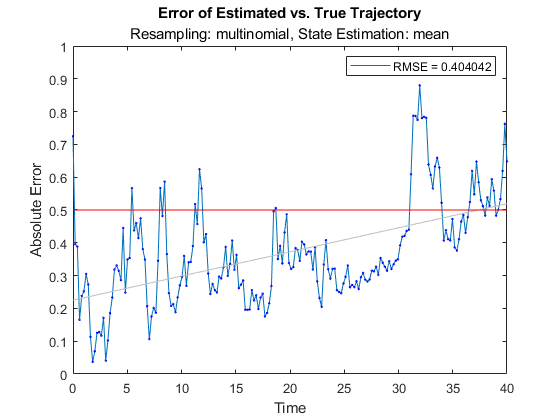

RMSE = 0.404042

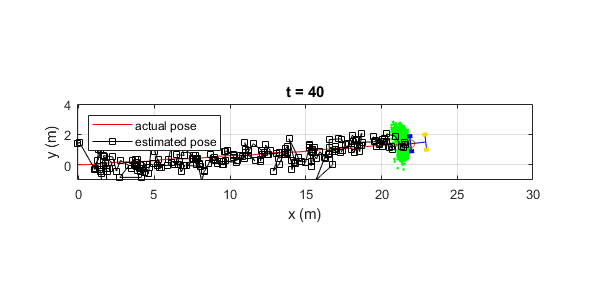

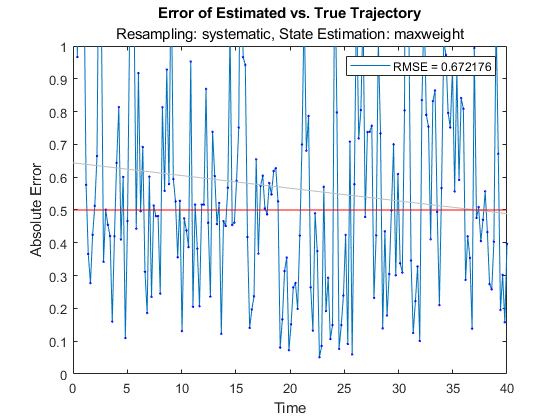

RMSE = 0.672176

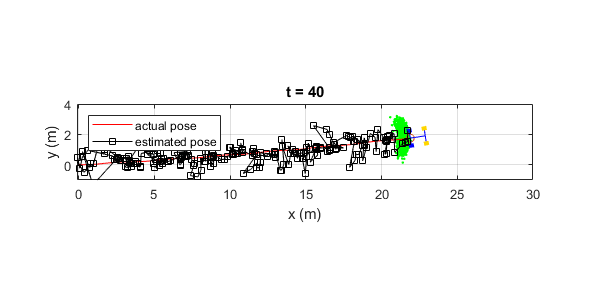

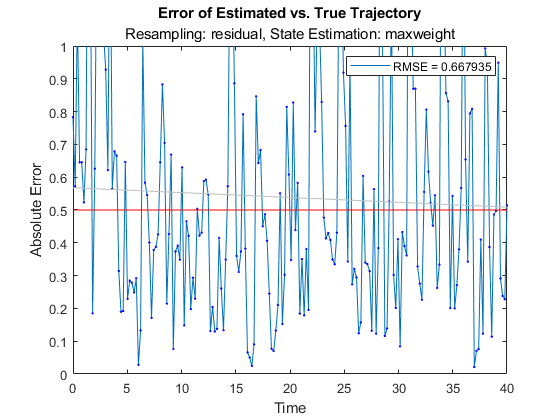

RMSE = 0.667935

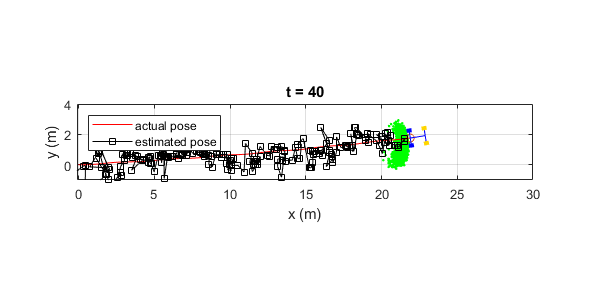

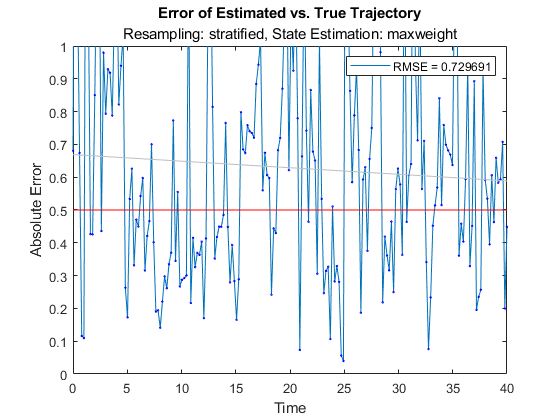

RMSE = 0.729691

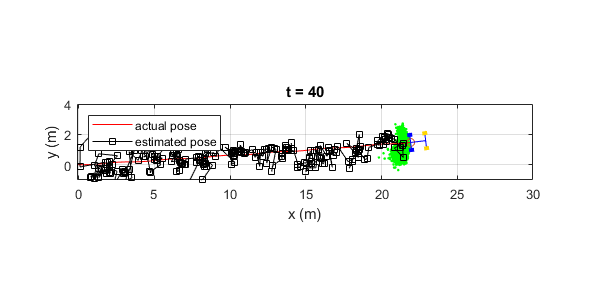

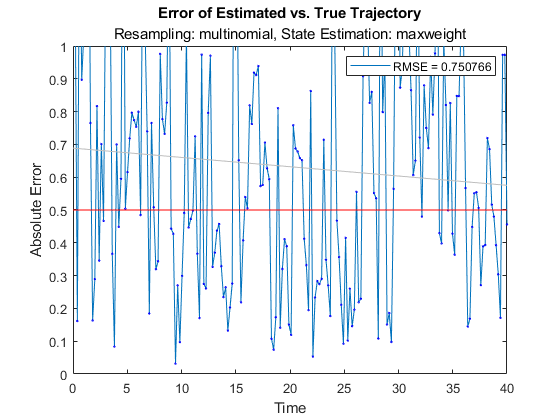

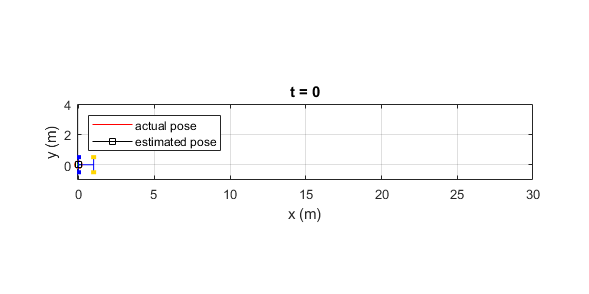

RMSE = 0.750766

%GPS Sensor Specifications
update_rate = 5; %Hz
accuracy = 2; 
Total_Steps = 800;

resample = ["systematic","residual","stratified","multinomial"];
stateEst = ["mean","maxweight"];

for sE = 1:length(stateEst)
    for rS = 1:length(resample)
        pf = stateEstimatorPF;

        % 5000 particles, 6 state variables (3 position, 3 velocity) - big Xt-1 in algorithm 
        initialize(pf, 5000, [initialPose(1:3)', 0, 0, 0], eye(6), 'CircularVariables',[0 0 1 0 0 0]);
        pf.StateEstimationMethod = stateEst(sE);
        pf.ResamplingMethod = resample(rS);
        
        % StateTransitionFcn - propogates the particles based on the velocity motion model (sd1-sd3 affects tracking performance)
        pf.StateTransitionFcn = @exampleHelperCarBotStateTransition;
        
        % MeasurementLikelihoodFcn - likelihood of each predicted particle based on error between particle and measurement, used to calculate importance weight  
        pf.MeasurementLikelihoodFcn = @exampleHelperCarBotMeasurementLikelihood;
        
        % initial Last best estimation for x, y and theta
        lastBestGuess = [0 0 0];

   
        r = rateControl(1/dt); %dt = 0.05


        reset(r);

        simulationTime = 0; 
        dist = [];
        time = 40;
        Samples = update_rate*time;
        trajSample = zeros(2,Samples);
        steps = 0; 
        
        while simulationTime < time % if time is not up
            steps = steps+1;
            % Generate motion command that is to be sent to the robot
            % NOTE there will be some discrepancy between the commanded motion and the
            % motion actually executed by the robot. 
            uCmd(1) = 0.7*abs(sin(simulationTime)) + 0.1;  % linear velocity
            uCmd(2) = 0.08*cos(simulationTime);            % angular velocity         % angular velocity
            
            drive(carbot, uCmd, simulationTime);%
                
            % Predict the carbot pose based on the motion model
            [statePred, covPred] = predict(pf, dt, uCmd);
        
            % Get GPS reading - this is just sampled from the pose but a variance
            % is added that aligns with different sensors online (GPS-RTK board and GNSS ZED-F9P)
        
            measurement = exampleHelperCarBotGetGPSReading(carbot, accuracy, uCmd, update_rate);
        
            % If measurement is available
            % , then call correct, otherwise just use
            % predicted result
            if ~isempty(measurement)
                [stateCorrected, covCorrected] = correct(pf, measurement');
            else
                stateCorrected = statePred;
                covCorrected = covPred;

            end
        
            lastBestGuess = stateCorrected(1:3);
        
            % Update plot
            if ~isempty(get(groot,'CurrentFigure')) % if figure is not prematurely killed
                updatePlot(carbot, pf, lastBestGuess, simulationTime, update_rate);
            else
                break
            end

            waitfor(r);
            
            % Update simulation time
            simulationTime = simulationTime + dt;
        end
        
        
       %plotting distance line 
        for s = 1:Samples
          step = s* Total_Steps/(update_rate*time);
          trajSample(:,s) = carbot.Trace(1:2,step+1); %only keep trajectory values that correspond to those saved for best guess
        end
        distx = [];
        disty = [];
        for i = 1:Samples
            distx(i) = norm(carbot.BGs(i,1)'-trajSample(1,i));
            disty(i) = norm(carbot.BGs(i,2)'-trajSample(2,i));
        end
        distance = sqrt(distx.^2 + disty.^2);
        RMSE = sqrt((mean(distance.^2)));
        sd = std(distance);
        threshold = 0.5.* ones(1, Samples);
        plottime = linspace(0,time,Samples);
        f1 = figure;
        f2 = figure;
        figure(f1);
        f1 = plot(plottime, distance);
        hold on;
        scatter(plottime, distance, 2, 'b');
        lsline
        hold on;
        plot(plottime, threshold, 'r'); %plot the threshold line
        title(['Error of Estimated vs. True Trajectory'])
        subtitle(['Resampling: ',sprintf('%s',resample(rS)), ', State Estimation: ',sprintf('%s',stateEst(sE))])
        xlabel('Time')
        ylabel('Absolute Error')
        xlim([0 time])
        ylim([0 1])
        legend(sprintf('RMSE = %f',RMSE));
        saveas(f1,['Resample',sprintf('%s',resample(rS)),'StateEst',sprintf('%s',stateEst(sE)),'.jpeg'])
        
        carbot = ExampleHelperCarBot(initialPose, dt);

        fprintf('RMSE = %f',RMSE);
    end 
end

## Reference

[1] S. Thrun, W. Burgard, D. Fox, Probabilistic Robotics, MIT Press, 2006

*Copyright 2015 The MathWorks, Inc.*